# Projeto - Eletromagnetismo e Ondulatória

## Modelando Antena Emissora

ant = spiralArchimedean('Turns', 5) % entre 3 e 6 voltas

ant =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 5
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 0
            TiltAxis: [1 0 0]
                Load: [1×1 lumpedElement]


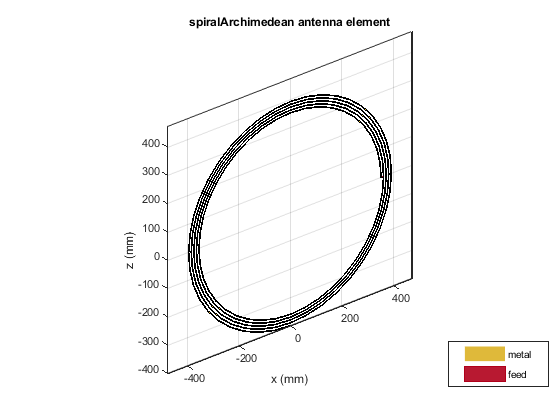

ant.NumArms = 1; % número de braços (ramos)  = 1
ant.Tilt = 90; % Inclinação da antena plano 3D
ant.OuterRadius = 40e-2; 
ant.InnerRadius = 35e-2;
show(ant)

## Impedância da Antena

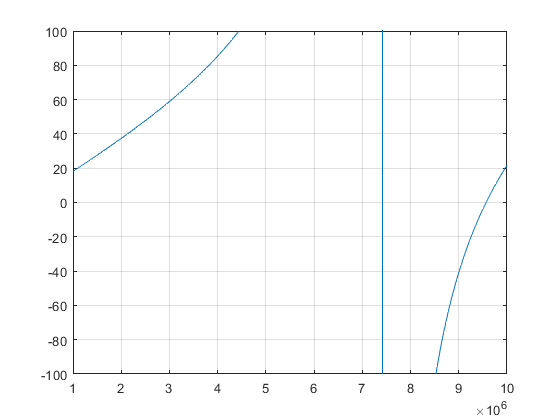

f = linspace(1e6, 1e7, 200);

impedancia = impedance(ant,f);
imaginario = imag(impedancia);
plot(f,imaginario)
ylim([-100, 100])
grid


index = find(imaginario == 0);   % May be multiple indexes, possibly
freq = f(index);

## Modelando Antena Receptora

ant2 = spiralArchimedean('Turns', 4) % entre 3 e 6 voltas

ant2 =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 4
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 0
            TiltAxis: [1 0 0]
                Load: [1×1 lumpedElement]


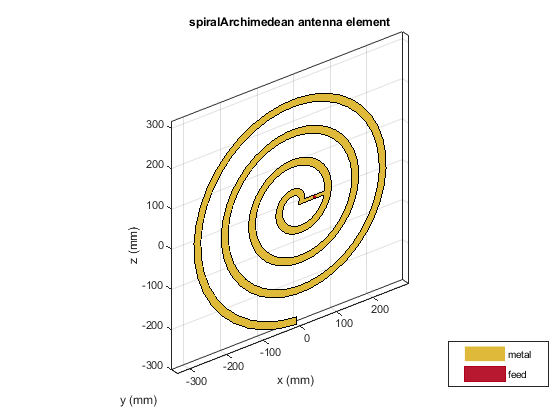

ant2.NumArms = 1; % número de braços (ramos)  = 1
ant2.Tilt = 90; % Inclinação da antena plano 3D
ant2.OuterRadius = 30e-2; 
ant2.InnerRadius = 10e-6;
show(ant2)